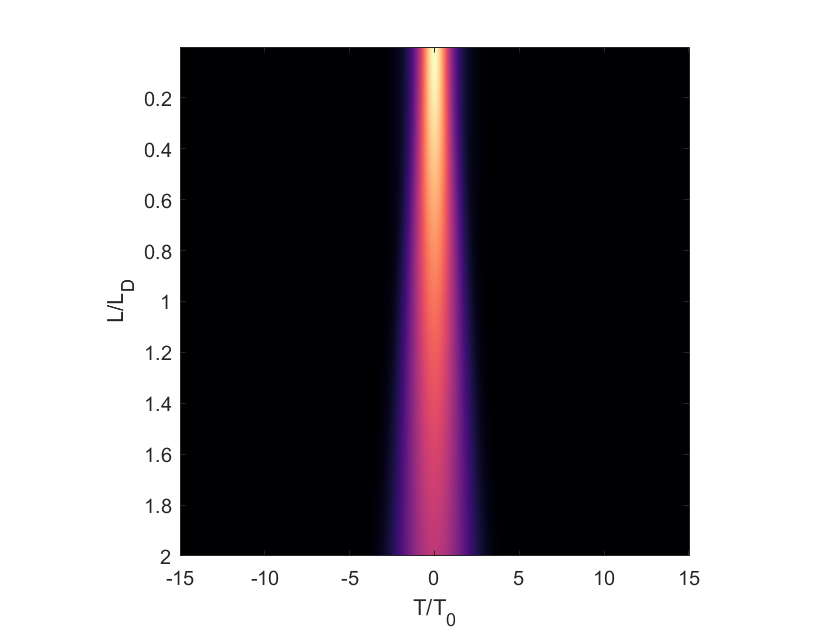

clear
clf
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%  Pulse evolution Simulation using the Split-step 
%   Fourier method
%  Manuel Ferrer 
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Physical Parameters

Beta2=0.02;      % GVD parameter
n0=1.45;         % linear refractive index  
n2=3E-20;        % non linear coefficient of the refractive index
lambda=1550E-9;  % wavelenght of the pulse
Po=1.5E13;       % Power of the pulse
t0= 5;           % Pulse Length 
w0=2*pi/lambda;  % Frequency of the pulse
c=3E8;           % Speed of light  
LD=t0^2/Beta2;   % Dispersion Length 
C=0;             % Chirp parameter 
L=2*LD;          % Length of the material 
eps0=8.854E-12;  % Permitivity of the free space

% Simulation parameters

n=1024;       % Number of points in the numerical mesh of the pulse 
tmax= 15*t0;  % Max values of time 
nn=1E04;      % Number of propagation steps


t=linspace(-tmax,tmax,n); % Time space
dt=abs(t(1)-t(2));        % Time space step

h=L/nn;                   % Spatial step (propagation step) 

dw=1/n/dt*2*pi;           % Reciprocal space step
omega=(-n/2:1:n/2-1)*dw;  % Frequency space


A=zeros(1E4,1024);        % Propagation matrix 

%A(1,:)=exp(-(1+1i*C)*(t/t0).^2);          %Initial Gaussian pulse
A(1,:)=sech(t/t0).*exp(-(1i*C)*(t/t0).^2); %Initial Hyperbolic secant 


%Normalization of the pulse amplitude 
A(1,:)= sqrt(Po)*A(1,:)./sqrt(sum(abs(A(1,:)).^2)*dt);


% Dispersion operator in Frequency space 
D=-1i*0.5*Beta2*(1i*omega).^2; 

%Non linear parameter 
gamm=2*n0*eps0*n2*w0;

%Split-Step Fourier Algorithim 
for ii=2:nn  
    N  = 1i*gamm*abs(A(ii-1,:)).^2; 
    A(ii,:)=exp(h*N).*ifft(fftshift(exp(h * D).*fftshift(fft(A(ii-1,:))))); 
end

% Propagation plot 
figure(1)
imagesc(t/t0,h*(1:nn)/LD,abs(A).^2)
colormap(slanCM('magma')) 
ylabel('L/L_D')
xlabel('T/T_0') 
axis square

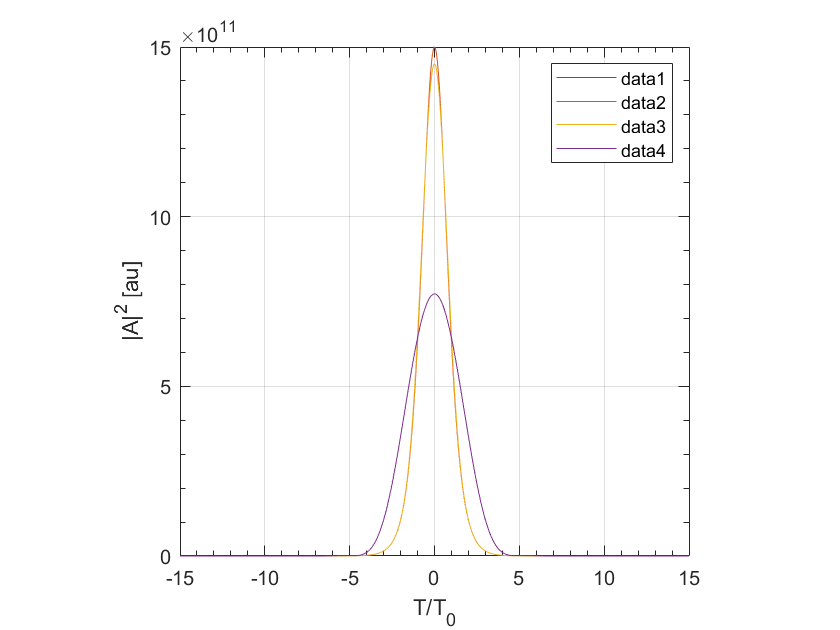


% Amplitude plots 
figure(3)
plot(t/t0,abs(A(10,:)).^2,t/t0,abs(A(100,:)).^2,t/t0,abs(A(1000,:)).^2,t/t0,abs(A(end,:)).^2)
legend()
grid on 
xlabel('T/T_0') 
ylabel('|A|^2 [au]')
axis square
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);

        
% Fourier Space of the propagation steps
F=zeros(size(A)); 
for ii=1:nn
    F(ii,:)=fftshift(fft(A(ii,:)));
end 
    











